Test algorithm S

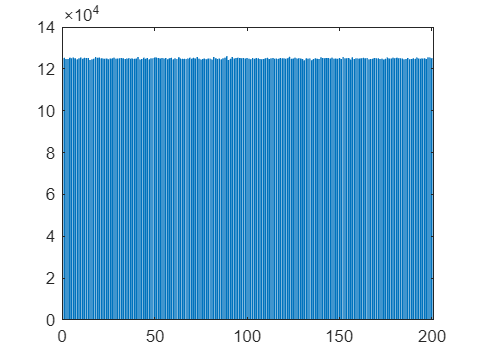

n_runs = 5000000;
n_toChoose = 5;
n_options = 200;
l_numbers = 1:n_options;
results = zeros(n_runs,n_toChoose);
counts = zeros(1,n_options);

parfor i=1:n_runs
    results(i,:) = randMfromN(l_numbers,n_options,n_toChoose);
end

for i=1:n_options
    counts(i) = sum(results(:)==i);
end

Px = (counts/n_runs);
Qx = (n_toChoose/n_options);

bar(counts)

min_count = min(counts)

min_count = 124087

max_count = max(counts)

max_count = 125976

expected = n_toChoose/n_options*n_runs

expected = 125000

divergence = sum(Px.*log(Px/Qx)) % Kullback–Leibler (KL) divergence

divergence = 1.4937e-05